clear, close all, clc

h5disp("higgs_100000_pt_1000_1200.h5");

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5");

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



sig_data = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');

bkgnd_data = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

histogram(sig_data(1,:),30);
hold on
title('Pt')
histogram(bkgnd_data(1,:),30);
legend('Signal','Background')
x_range = [1083 1170];
[n_back_pt, n_sig_pt, ratio_pt] = n_calc(bkgnd_data(1,:), sig_data(1,:), x_range)

n_back_pt = 45980

n_sig_pt = 61708

ratio_pt = 1.3421

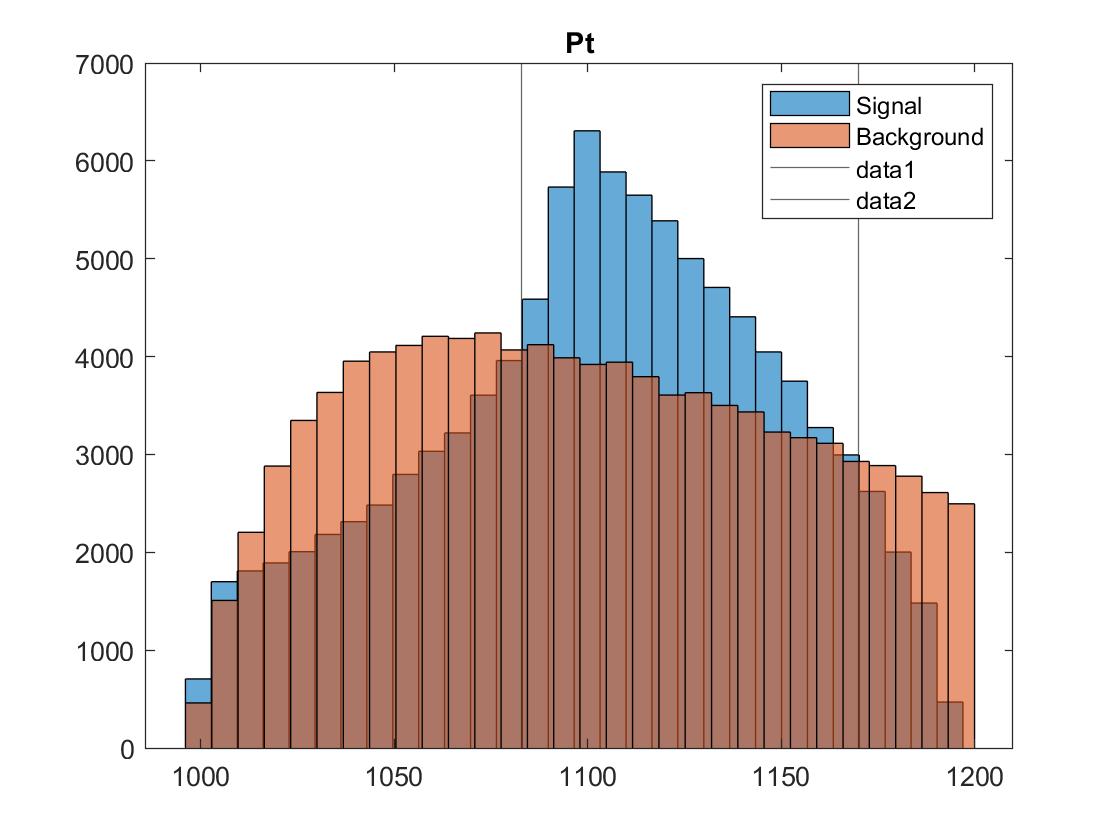

xline(x_range(1))
xline(x_range(2))
hold off

The transverse momenta has a decent amount of discrimination power, over the interval 1083 to 1170 the ratio between Higgs particals and QCD particals is 1.3421. In addition the means are different.

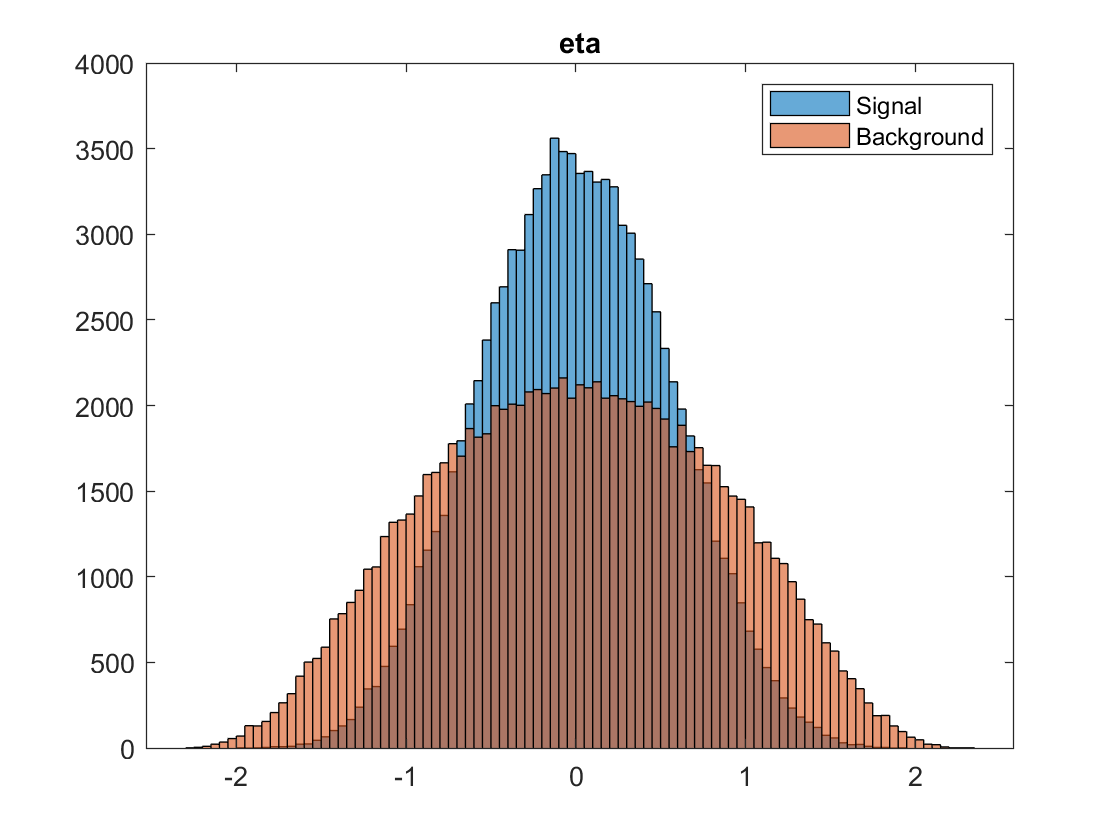


histogram(sig_data(2,:))
title('eta')
hold on
histogram(bkgnd_data(2,:))
hold off
legend('Signal','Background')

The ETA does not provide much discimination power as the distributions of signal and background data have the same mean. Meaning if you have a generic set of data and you're goal is to pick out the signal. The usual method would be to subtract the background signal from the generic set of data. In this case that wouldn't provide much detail since the distributions have the same mean.

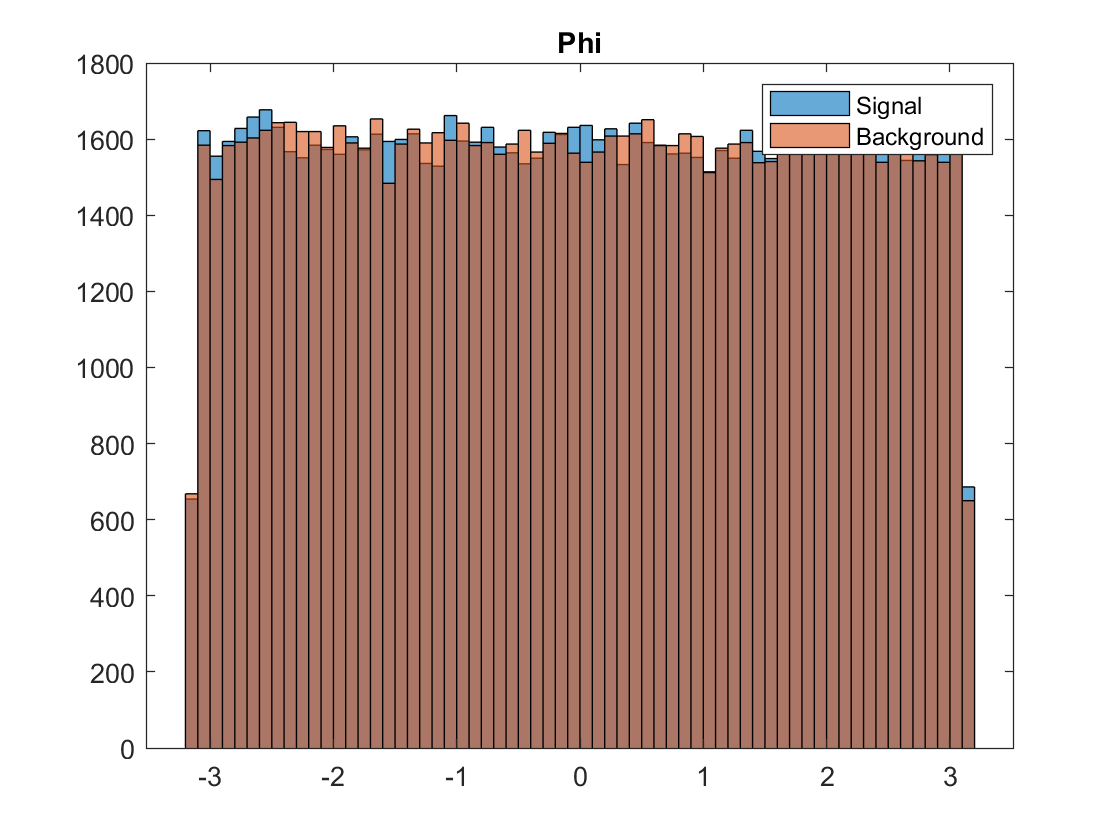


histogram(sig_data(3,:))
title('Phi')
hold on
histogram(bkgnd_data(3,:))
hold off
legend('Signal','Background')

Phi seems to have essentially zero discrimination power or correlation since the signal and background distribution are both entirely evenly distributied over the full interval -pi to pi. 


histogram(sig_data(4,:))
title('Mass')
hold on
histogram(bkgnd_data(4,:))
legend('Signal','Background')
x_range = [120 130];
[n_back_mass, n_sig_mass, ratio_mass] = n_calc(bkgnd_data(4,:), sig_data(4,:), x_range)

n_back_mass = 6414

n_sig_mass = 75829

ratio_mass = 11.8224

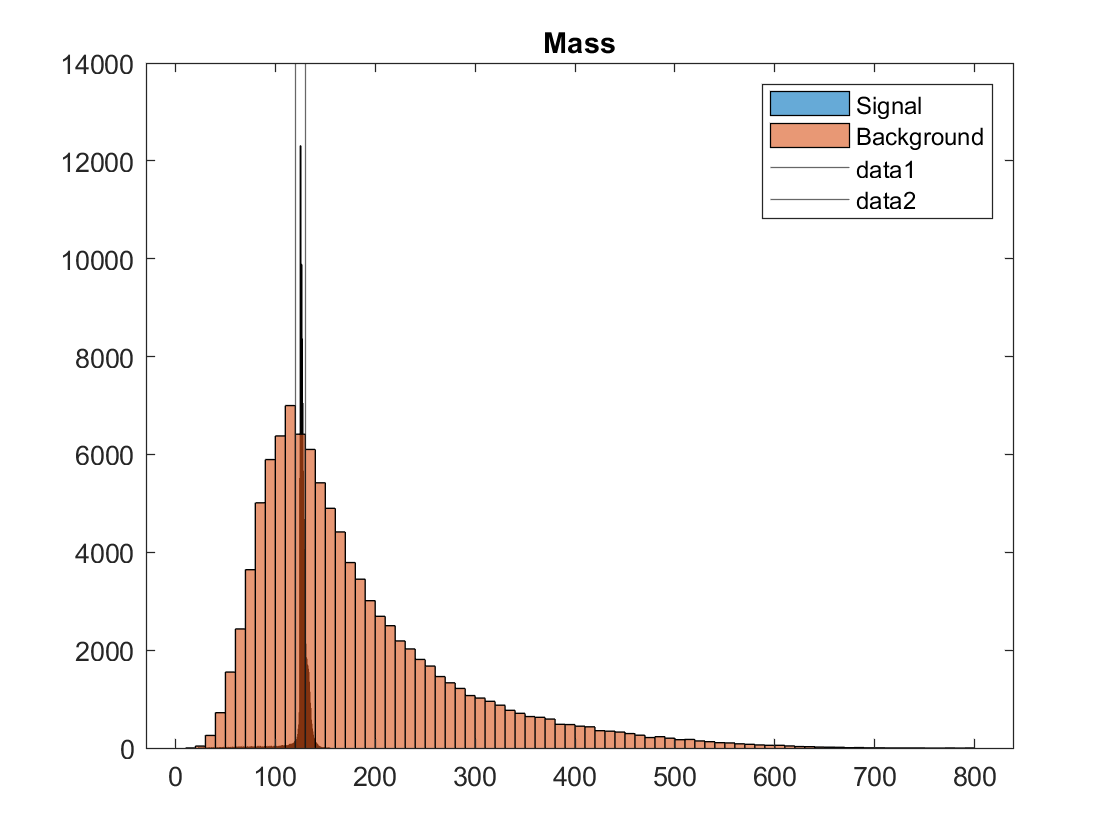

xline(x_range(1))
xline(x_range(2))
hold off

Mass has a verly large discrimination power since the ratio between Higgs particals and QCD particals is 1.3421 on the interval 120 to 130. In addition this is a relatively tight interval compared to the entire interval 0 to 800. 


histogram(sig_data(5,:))
title('ee2')
hold on
histogram(bkgnd_data(5,:))
legend('Signal','Background')
x_range = [0.05 0.065];
[n_back_pt, n_sig_pt, ratio_pt] = n_calc(bkgnd_data(5,:), sig_data(5,:), x_range)

n_back_pt = 10137

n_sig_pt = 60170

ratio_pt = 5.9357

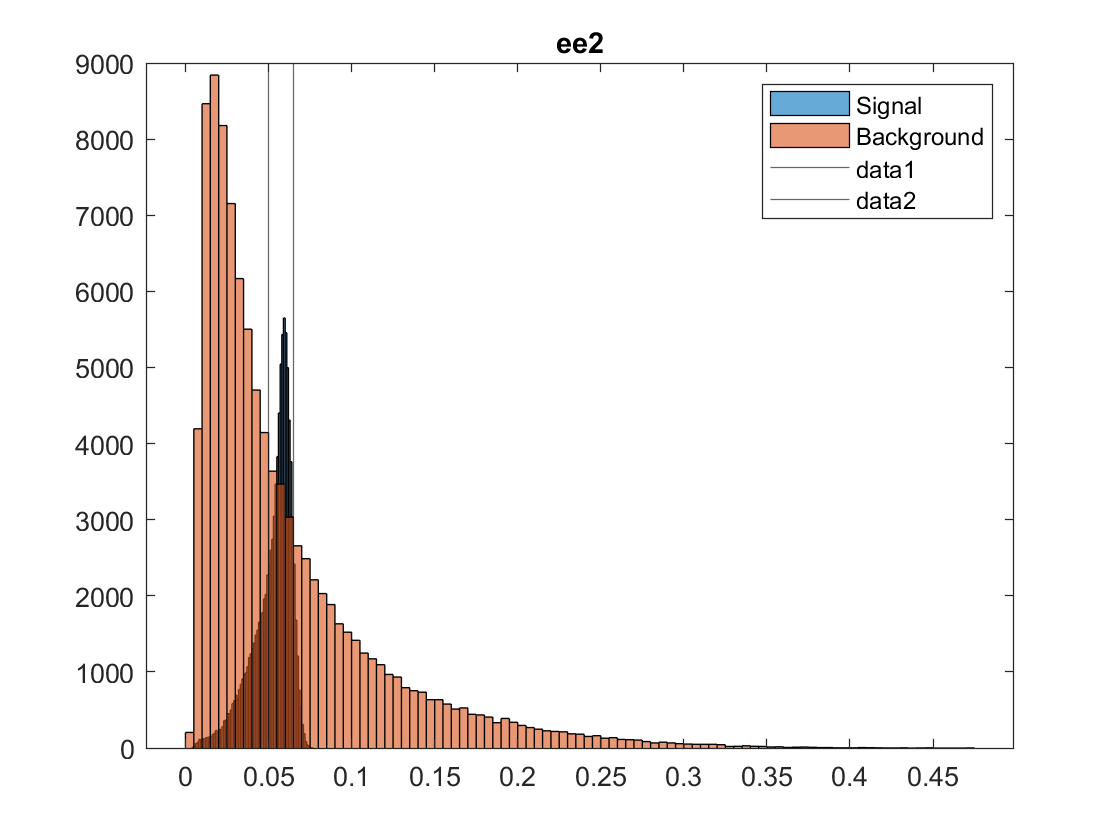

xline(x_range(1))
xline(x_range(2))
hold off

The Energy Correlation function with i=2 also has a large discrimination power since the ratio between the numebr of Higgs particals to the number of QCD particals is 5.9357 over the interval 0.05 to 0.065 which is relatively small compared to the overall 0 to 0.5.

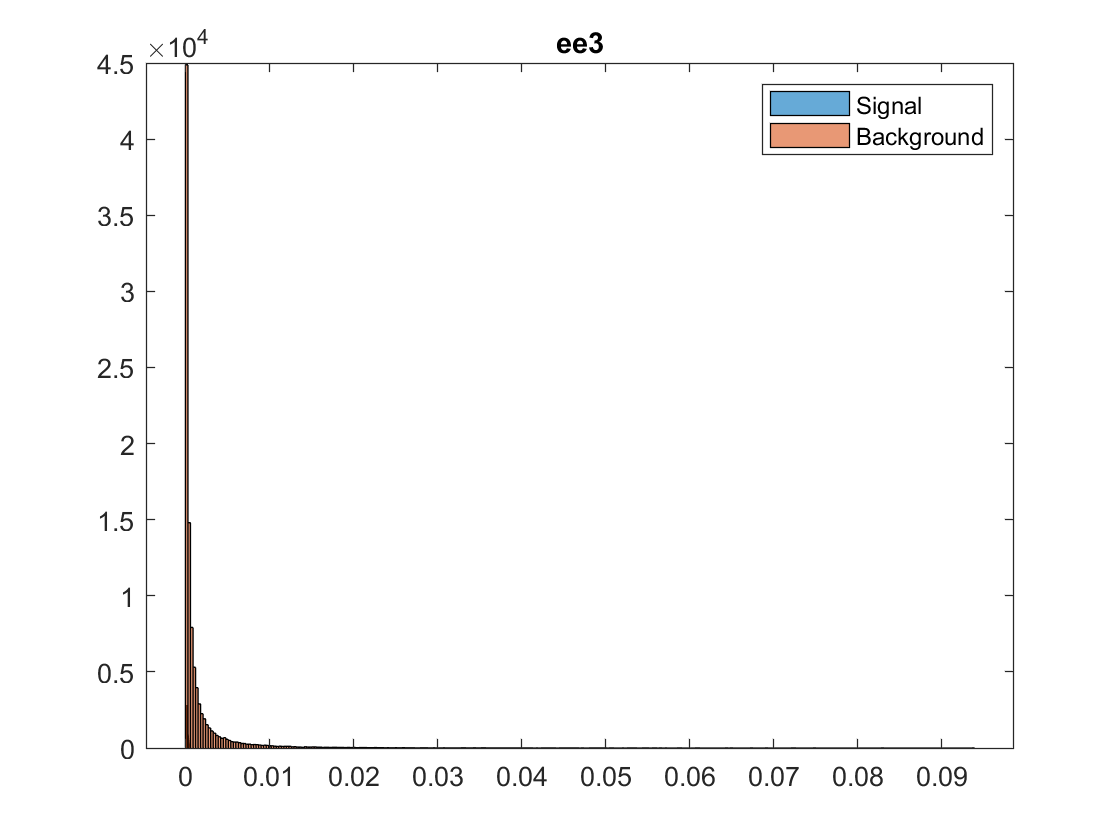

histogram(sig_data(6,:))
title('ee3')
hold on
histogram(bkgnd_data(6,:))
hold off
legend('Signal','Background')

The Energy Correlation function with i=3  does not have much discrimination power since the distributions are primarily the same but the signal distribution is far more reduced compared to the background distribution.

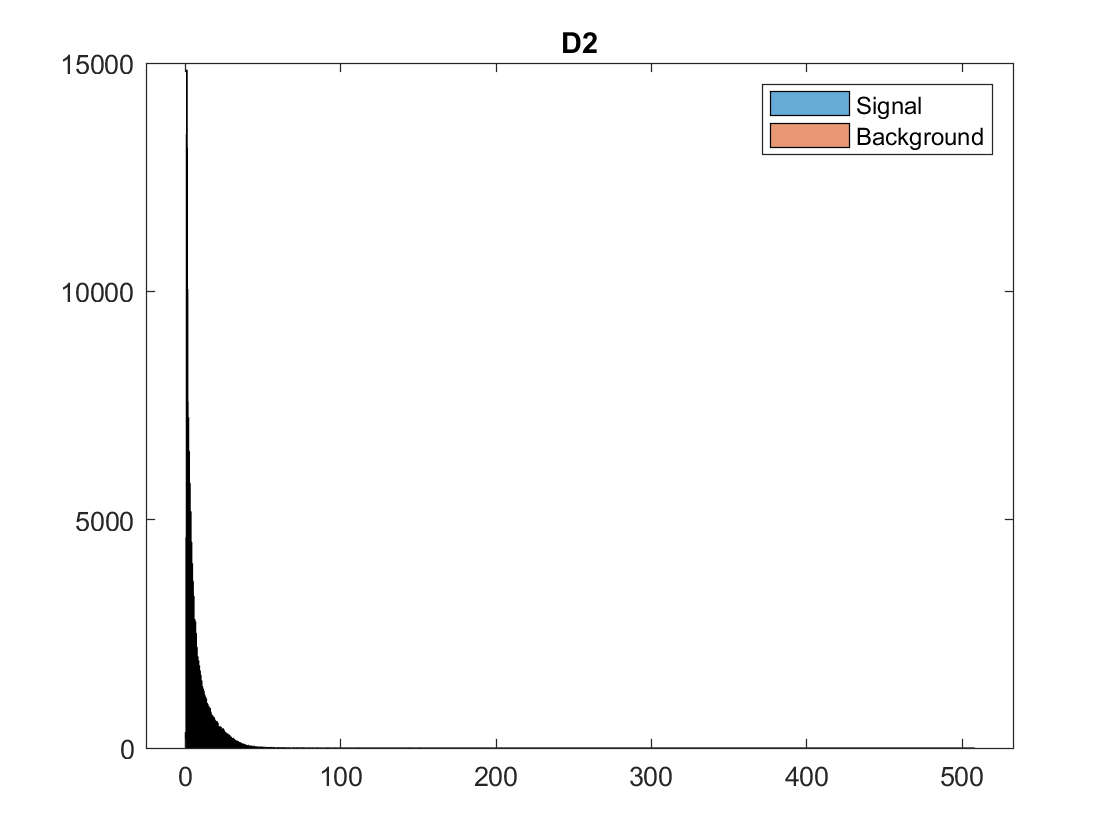


histogram(sig_data(7,:))
title('D2')
hold on
histogram(bkgnd_data(7,:))
hold off
legend('Signal','Background')

D2 does not have much discrimination power since the distributions are primarily the same but the signal distribution is far more reduced compared to the background distribution.

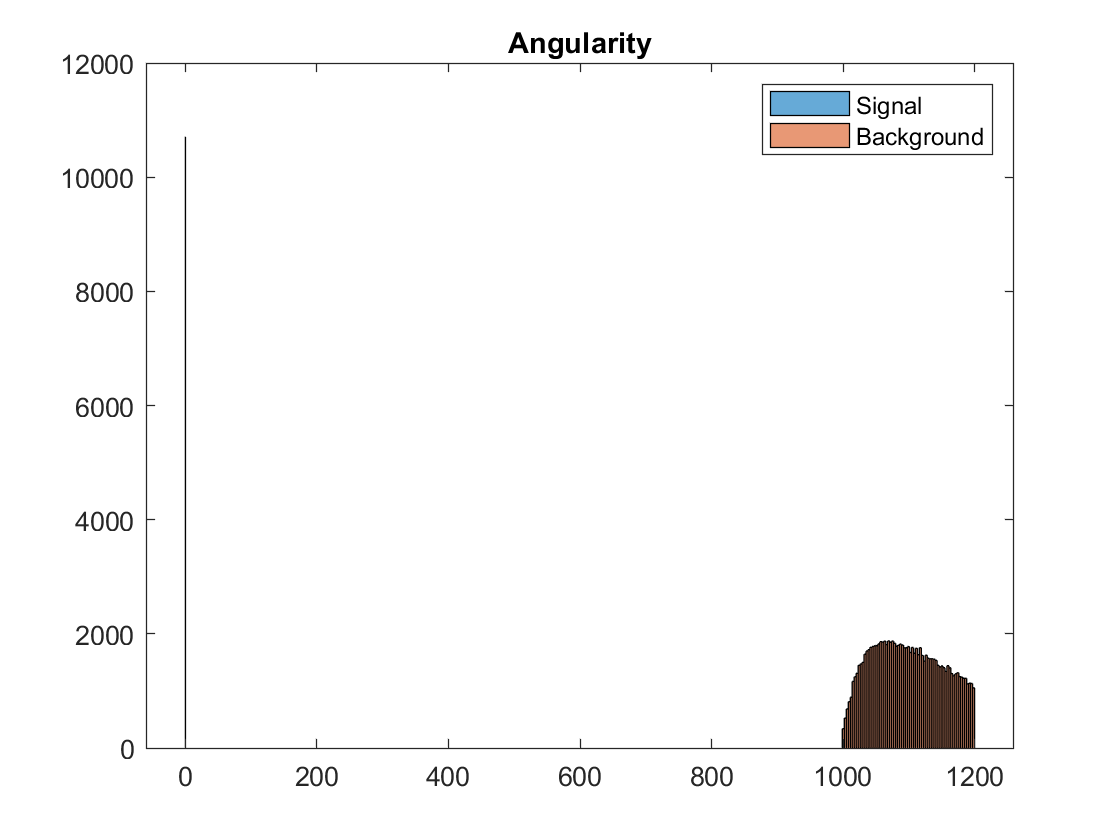

histogram(sig_data(8,:))
title('Angularity')
hold on
histogram(bkgnd_data(1,:))
hold off
legend('Signal','Background')

I've honestly don't have much to say about angularity. It doesn't appear to have any obvious correlation to any other parameter and the signal and background are completely different distributions. 

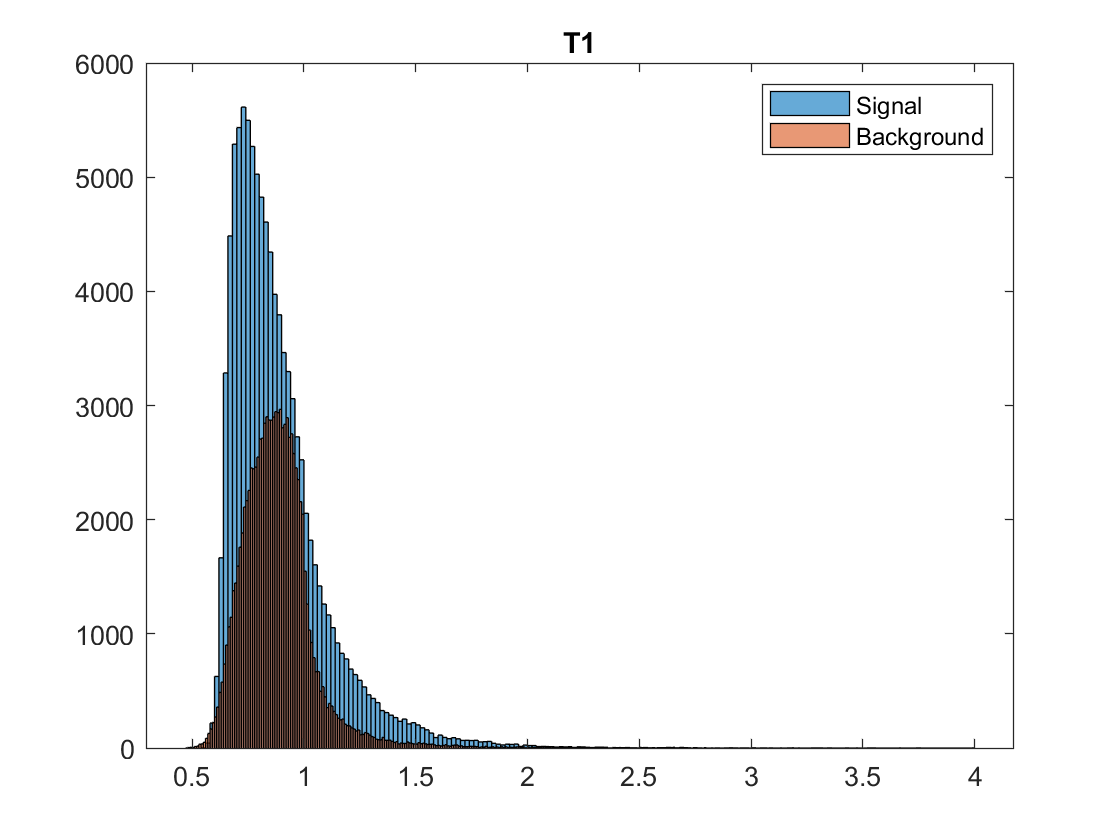


histogram(sig_data(9,:))
title('T1')
hold on
histogram(bkgnd_data(9,:))
hold off
legend('Signal','Background')

The T1 doesn't have much discrimination power despite the signal overlapping the bakground distribution but since it overlaps over virtually the entire interval it doesn't really discriminate.


histogram(sig_data(10,:))
title('T2')
hold on
histogram(bkgnd_data(10,:))
legend('Signal','Background')
x_range = [0.08 0.28];
[n_back_t2, n_sig_t2, ratio_t2] = n_calc(bkgnd_data(10,:), sig_data(10,:), x_range)

n_back_t2 = 12794

n_sig_t2 = 58796

ratio_t2 = 4.5956

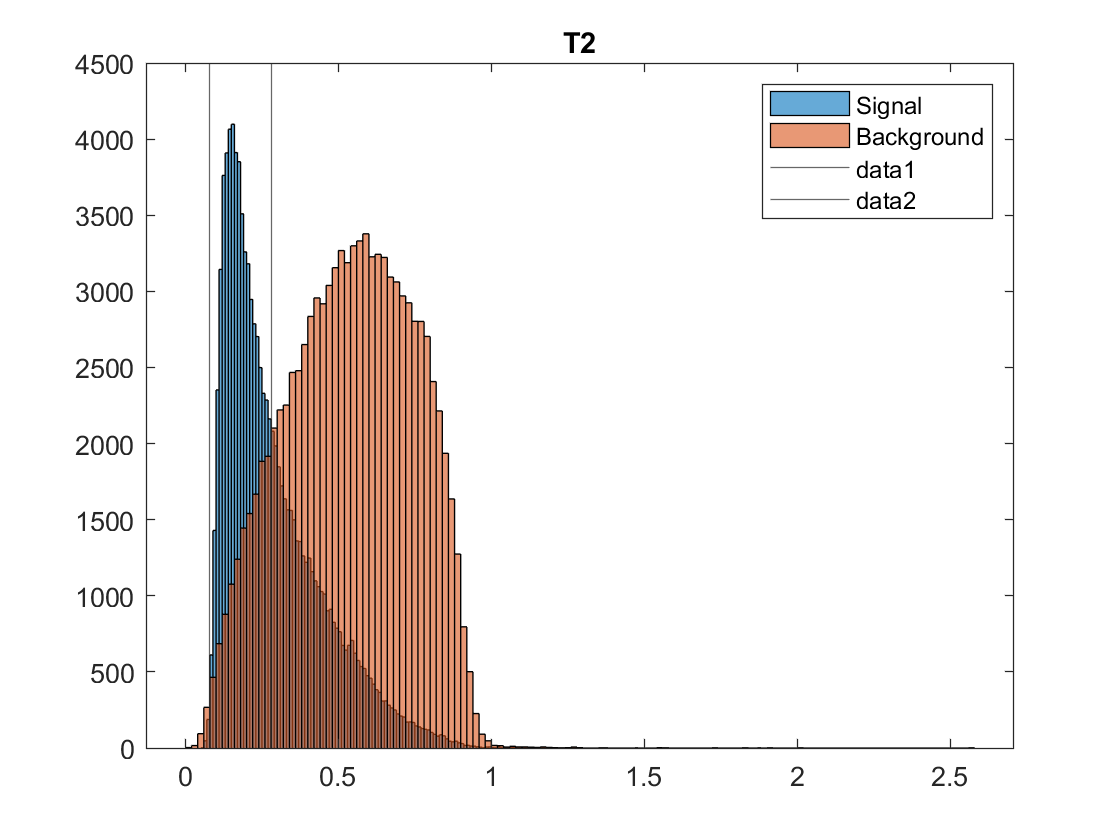

xline(x_range(1))
xline(x_range(2))
hold off

The t2 also has a large discrimination power since the ratio between the numebr of Higgs particals to the number of QCD particals is 4.5956 over the interval 0.08 to 0.28 which is relatively small compared to the overall 0 to 2.5.


histogram(sig_data(11,:))
title('T3')
hold on
histogram(bkgnd_data(11,:))
legend('Signal','Background')
x_range = [0 0.29];
[n_back_t3, n_sig_t3, ratio_t3] = n_calc(bkgnd_data(11,:), sig_data(11,:), x_range)

n_back_t3 = 27061

n_sig_t3 = 82283

ratio_t3 = 3.0406

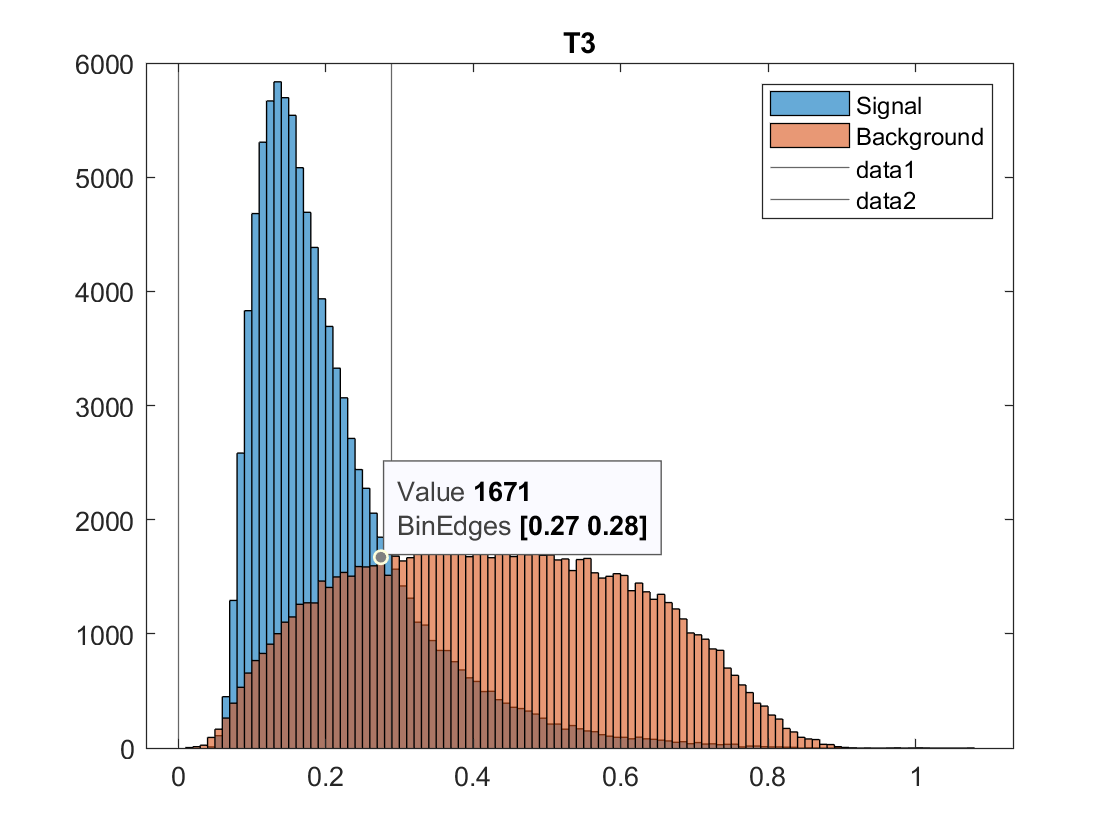

xline(x_range(1))
xline(x_range(2))
hold off

The T3 also has a large discrimination power since the ratio between the numebr of Higgs particals to the number of QCD particals is 3.0406 over the interval 0 to 0.29 which is relatively small compared to the overall 0 to 1.

histogram(sig_data(12,:))
title('T21')
hold on
histogram(bkgnd_data(12,:))
legend('Signal','Background')
x_range = [0.06 0.35];
[n_back_t21, n_sig_t21, ratio_t21] = n_calc(bkgnd_data(12,:), sig_data(12,:), x_range)

n_back_t21 = 13703

n_sig_t21 = 60352

ratio_t21 = 4.4043

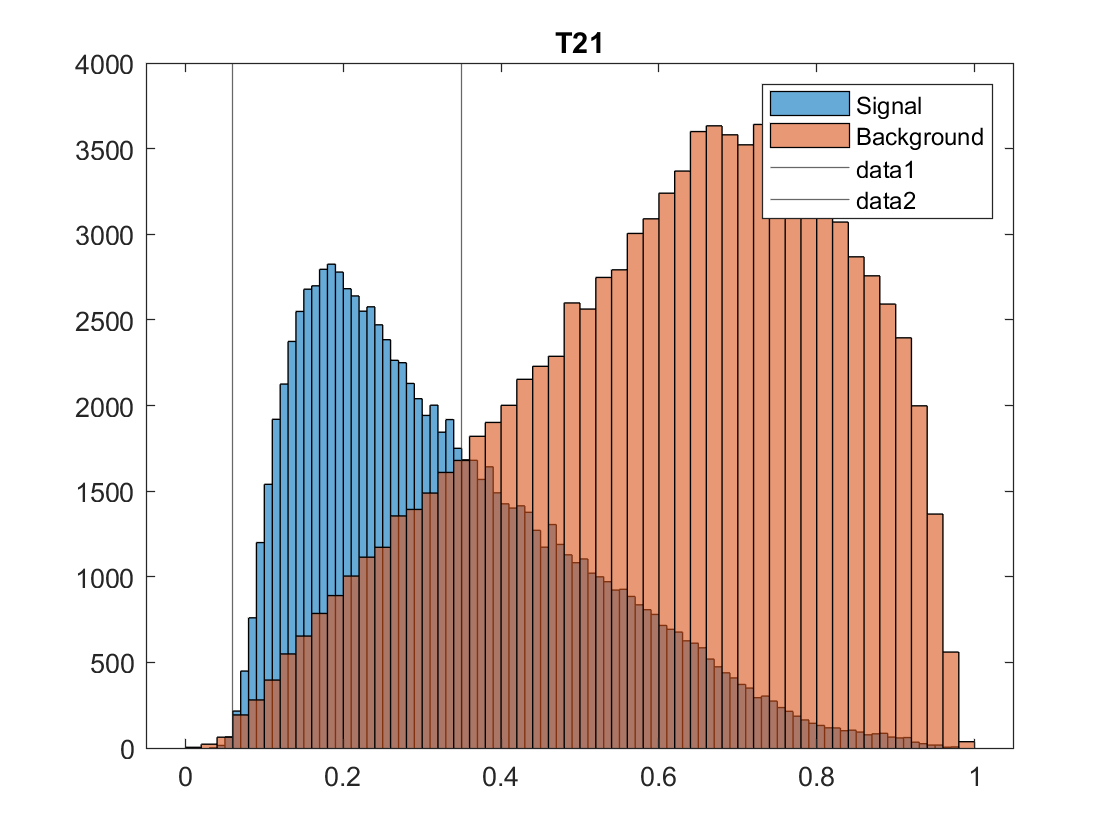

xline(x_range(1))
xline(x_range(2))
hold off

The T21 also has a large discrimination power since the ratio between the numebr of Higgs particals to the number of QCD particals is 4.4043 over the interval 0.06 to 0.35 which is relatively small compared to the overall 0 to 1.


histogram(sig_data(13,:))
title('T32')
hold on
histogram(bkgnd_data(13,:))
legend('Signal','Background')
x_range = [0.315 0.81];
[n_back_t32, n_sig_t32, ratio_t32] = n_calc(bkgnd_data(13,:), sig_data(13,:), x_range)

n_back_t32 = 48607

n_sig_t32 = 58381

ratio_t32 = 1.2011

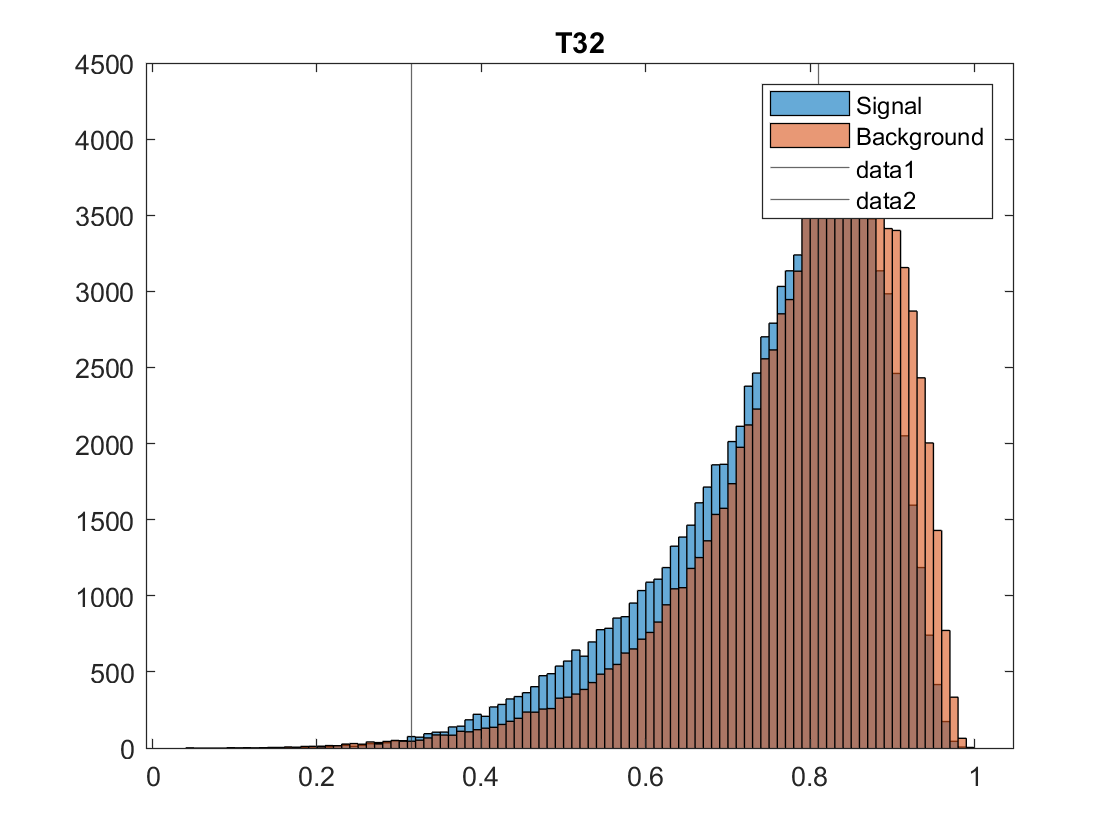

xline(x_range(1))
xline(x_range(2))
hold off

The T32 has a relatively small discrimination power since the ratio between the numebr of Higgs particals to the number of QCD particals is 1.2011 over the interval 0.315 to 0.81 which is relatively large compared to the overall 0 to 1.

histogram(sig_data(14,:))
title('ktdeltar')
hold on
histogram(bkgnd_data(14,:))
legend('Signal','Background')
x_range = [0.19 0.3];
[n_back_kt, n_sig_kt, ratio_kt] = n_calc(bkgnd_data(14,:), sig_data(14,:), x_range)

n_back_kt = 13788

n_sig_kt = 67704

ratio_kt = 4.9104

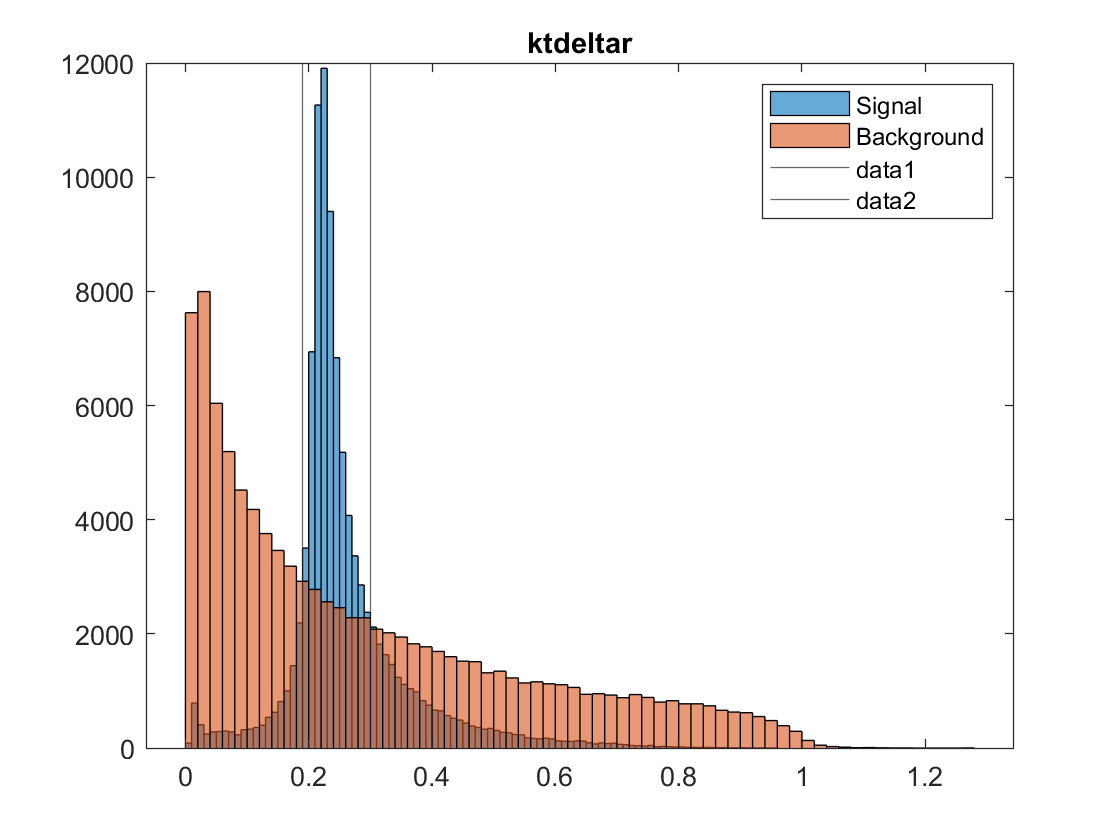

xline(x_range(1))
xline(x_range(2))
hold off

The KtDeltaR also has a large discrimination power since the ratio between the numebr of Higgs particals to the number of QCD particals is 4.9104 over the interval 0.19 to 0.3 which is relatively small compared to the overall 0 to 1.2.

function [n_bkgnd, n_sig, ratio] = n_calc(bkgnd, sig, x_range)
n_bkgnd = 0;
n_sig = 0;
for i = 1:length(bkgnd)
    if bkgnd(i) > x_range(1) && bkgnd(i) < x_range(2)
        n_bkgnd = 1 + n_bkgnd;
    end
    if sig(i) > x_range(1) && sig(i) < x_range(2)
        n_sig = 1 + n_sig;
    end
end
ratio = n_sig/n_bkgnd;
end